# Delio's Second Example

L = [3 4 sqrt(10) pi];
numEigs=6;

## The basic graph

Calculate and display the first few eigenvalues and eigenfunctions;

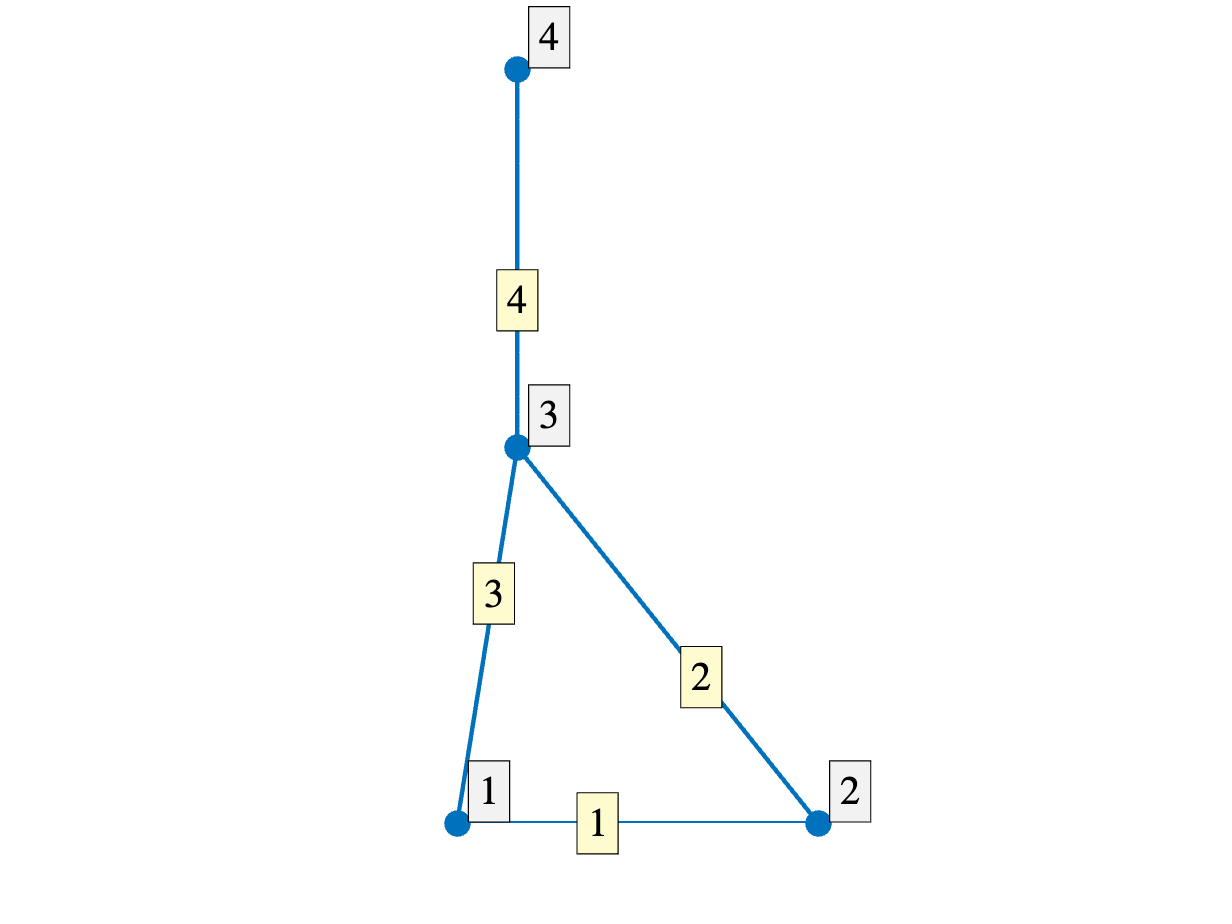

Phi1= quantumGraphFromTemplate('balalaika',Lvec=L,discretization='Chebyshev');
Phi1.plot('layout');

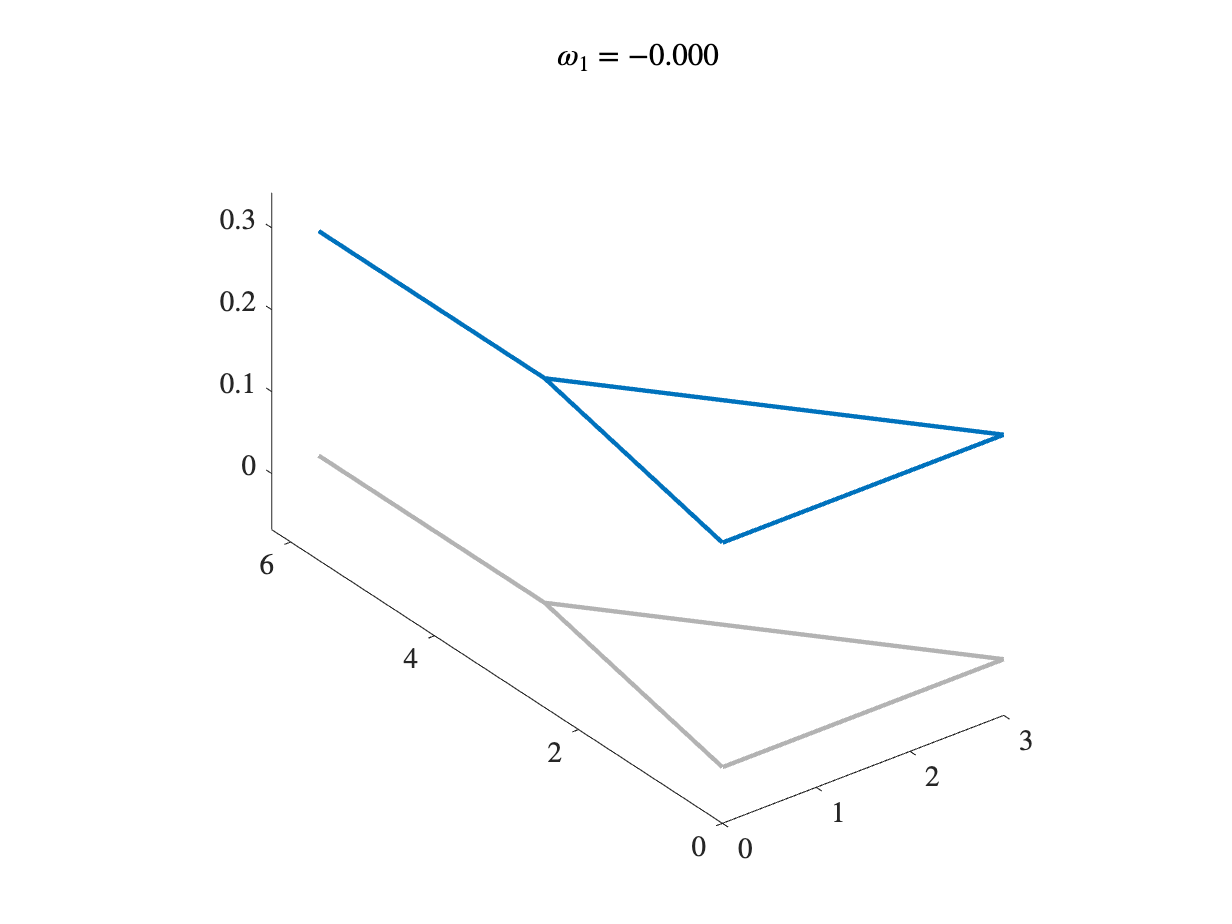

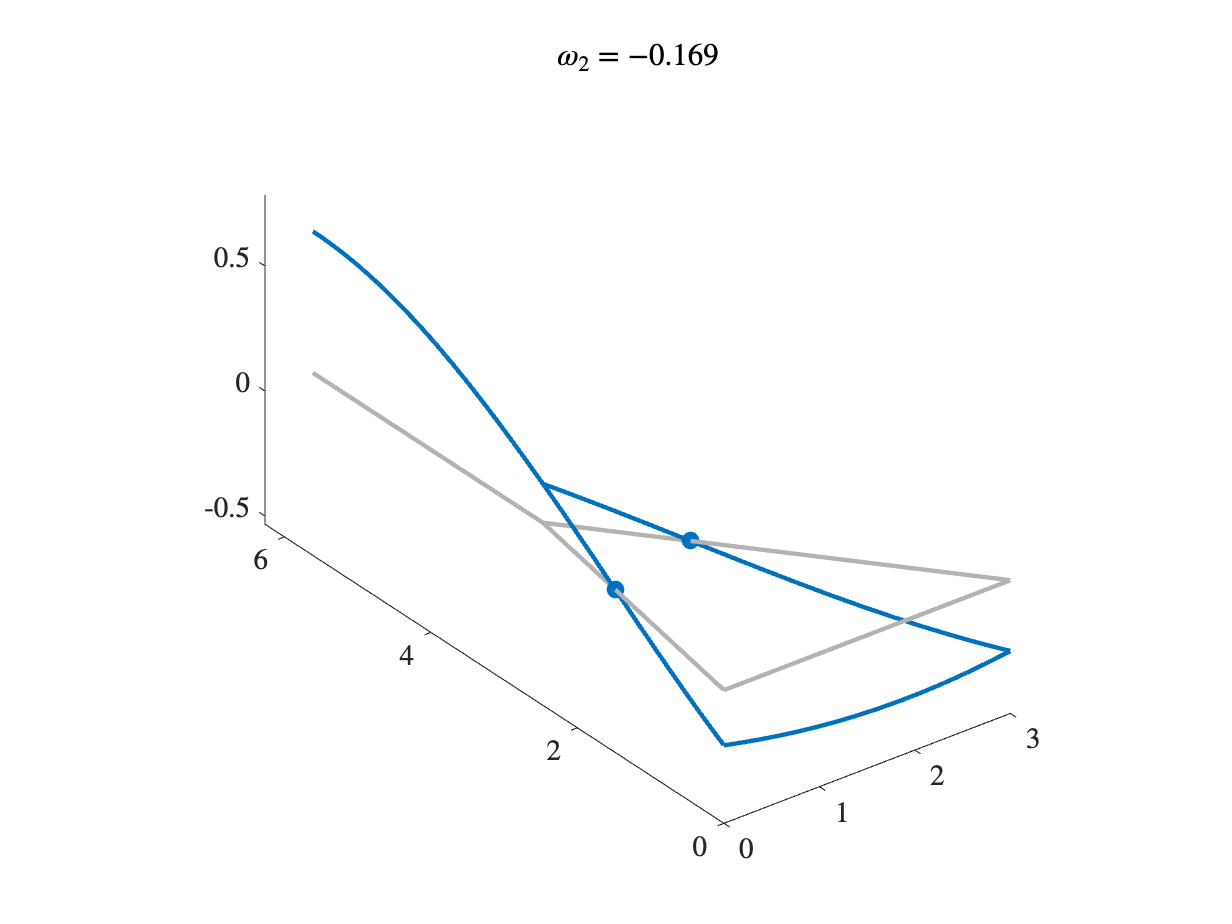

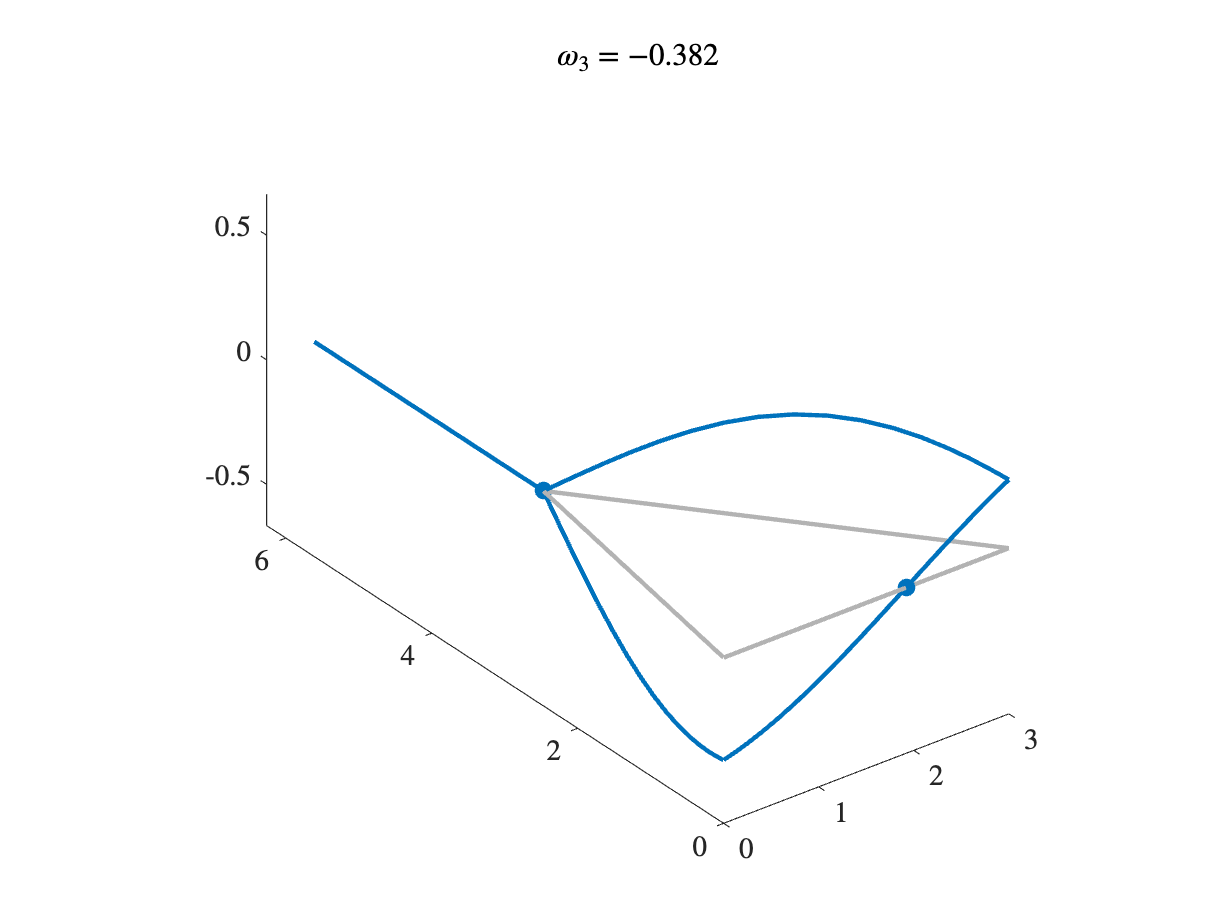

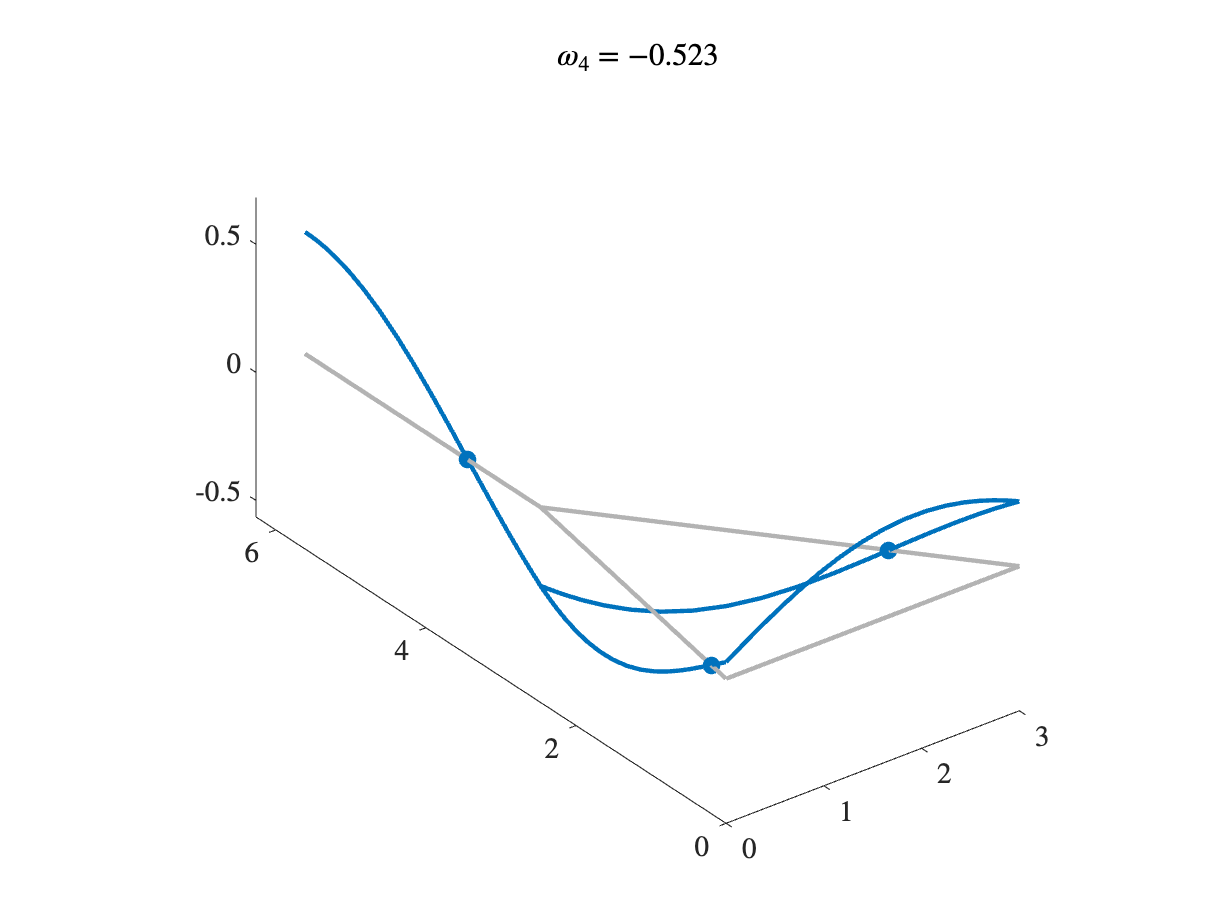

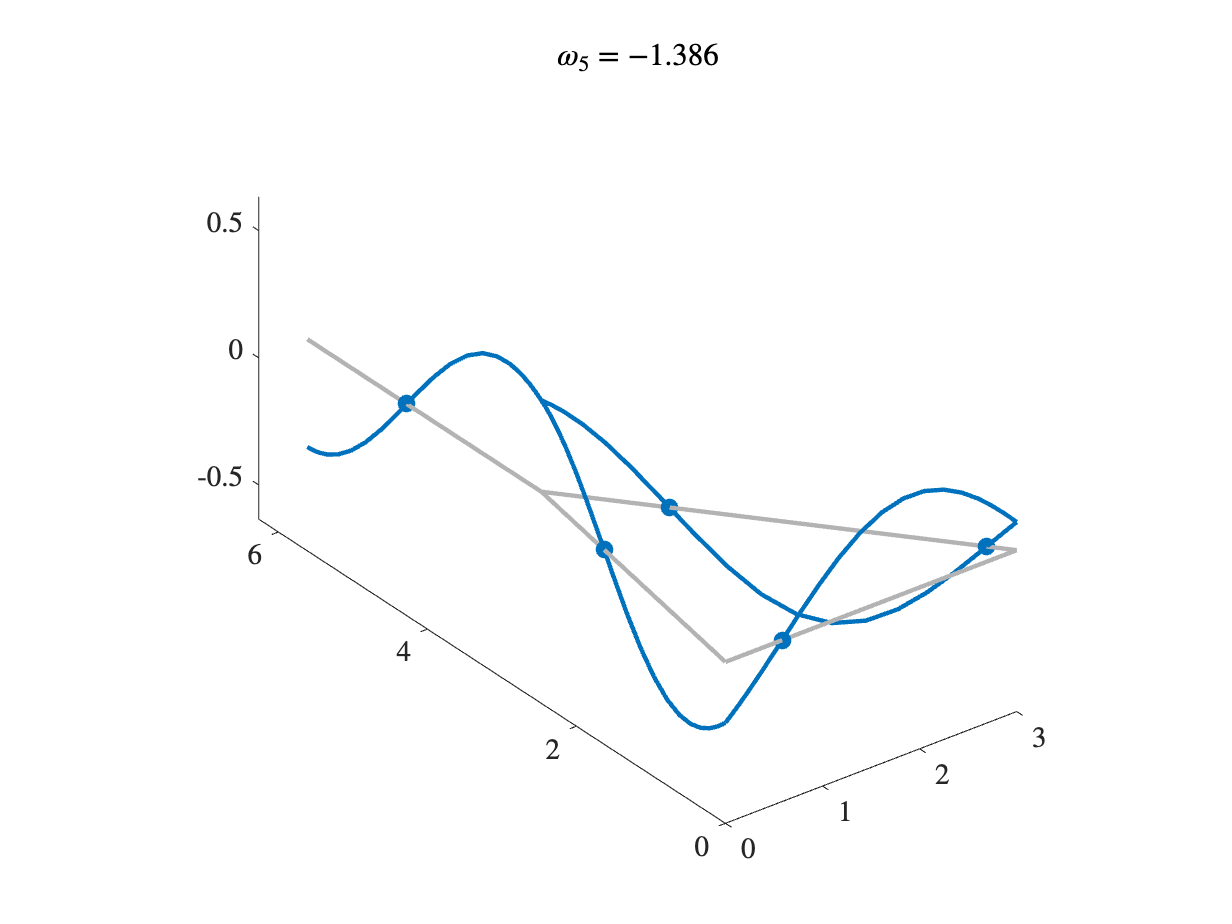

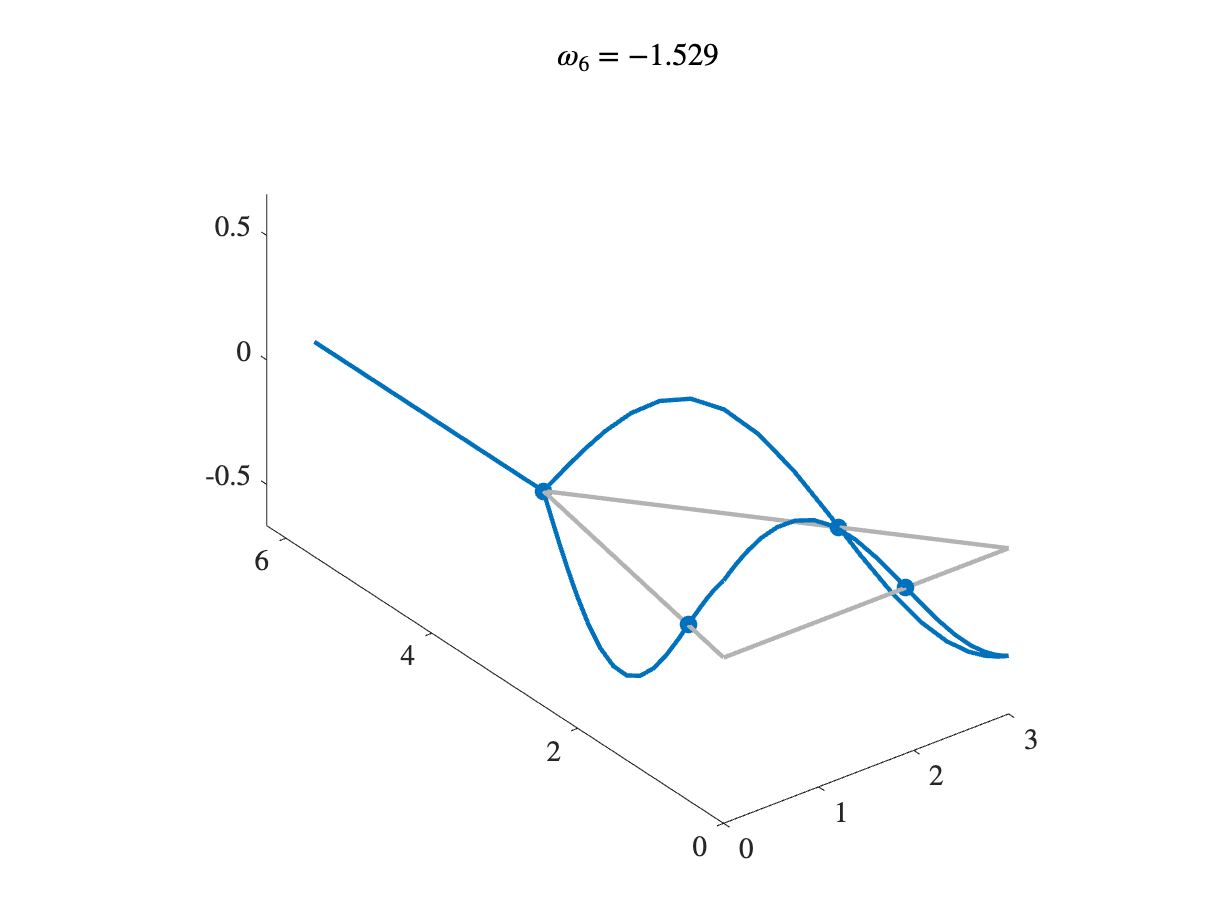

[V1,d1]=Phi1.eigs(numEigs);
for k=1:numEigs
    figure
    Phi1.plot(V1(:,k));
    title(sprintf('$\\omega_{%i} = %0.3f$',k,d1(k)))
end

## The graph with all vertices merged to make a clover

This should have larger (more negative) eigenvalues

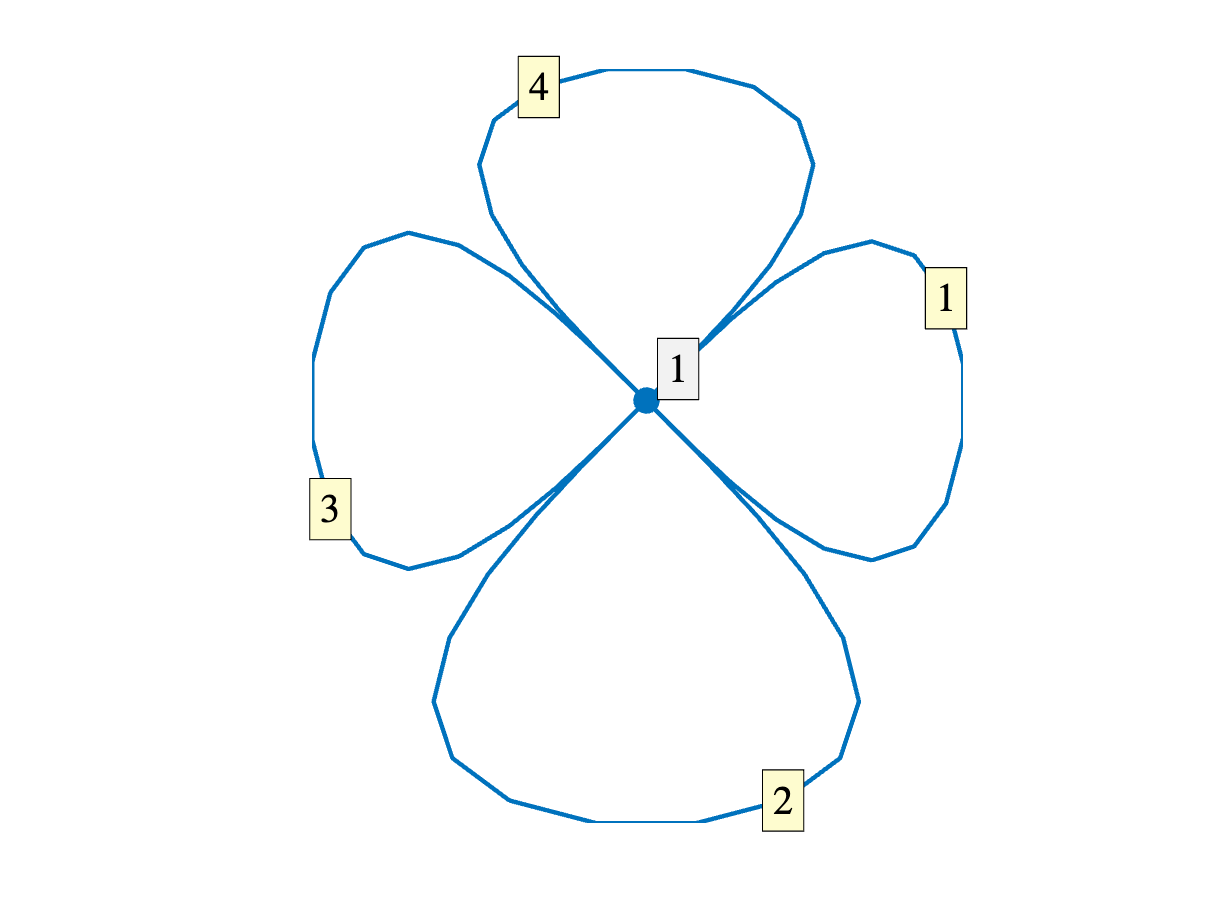

Phi2= quantumGraphFromTemplate('clover',nLeaves=4,Lvec=L,discretization='Chebyshev');
Phi2.plot('layout');

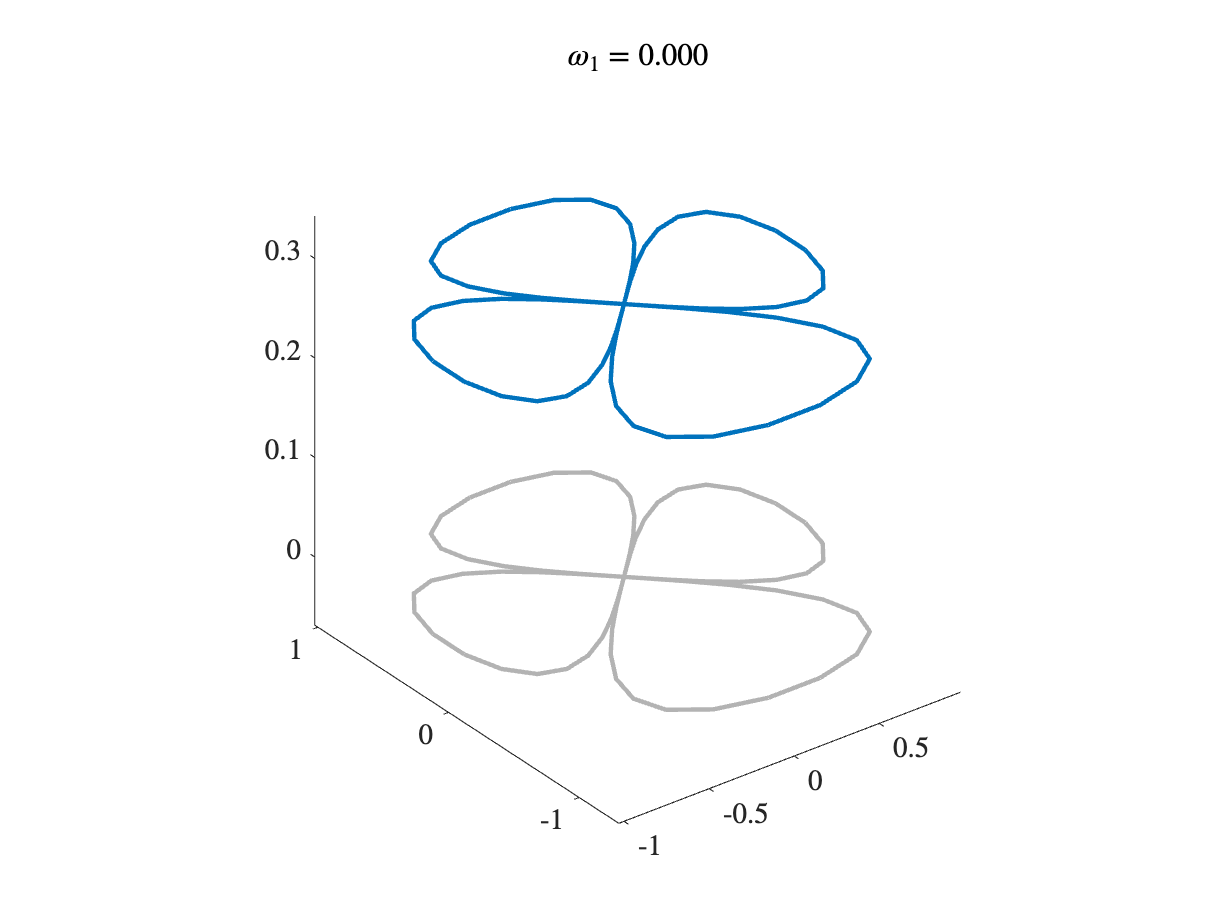

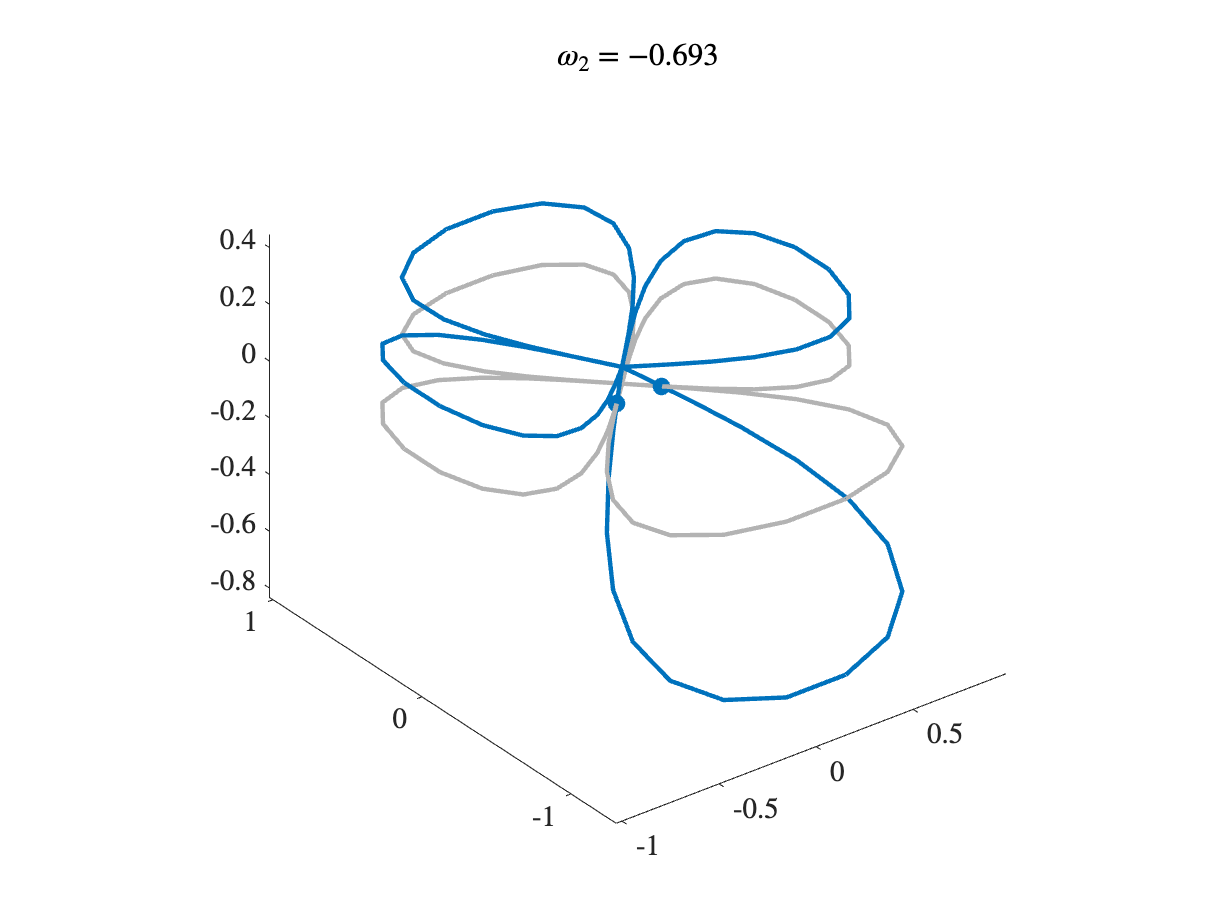

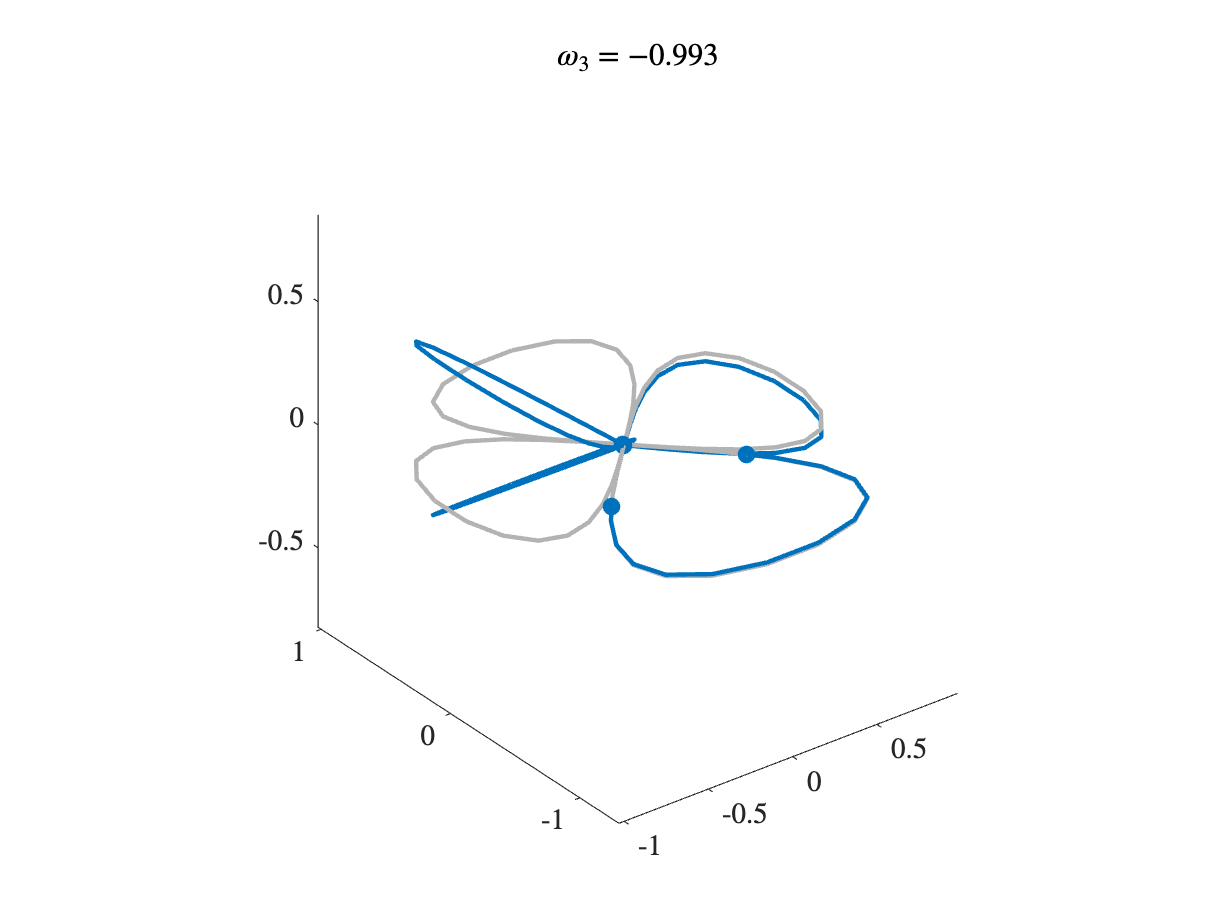

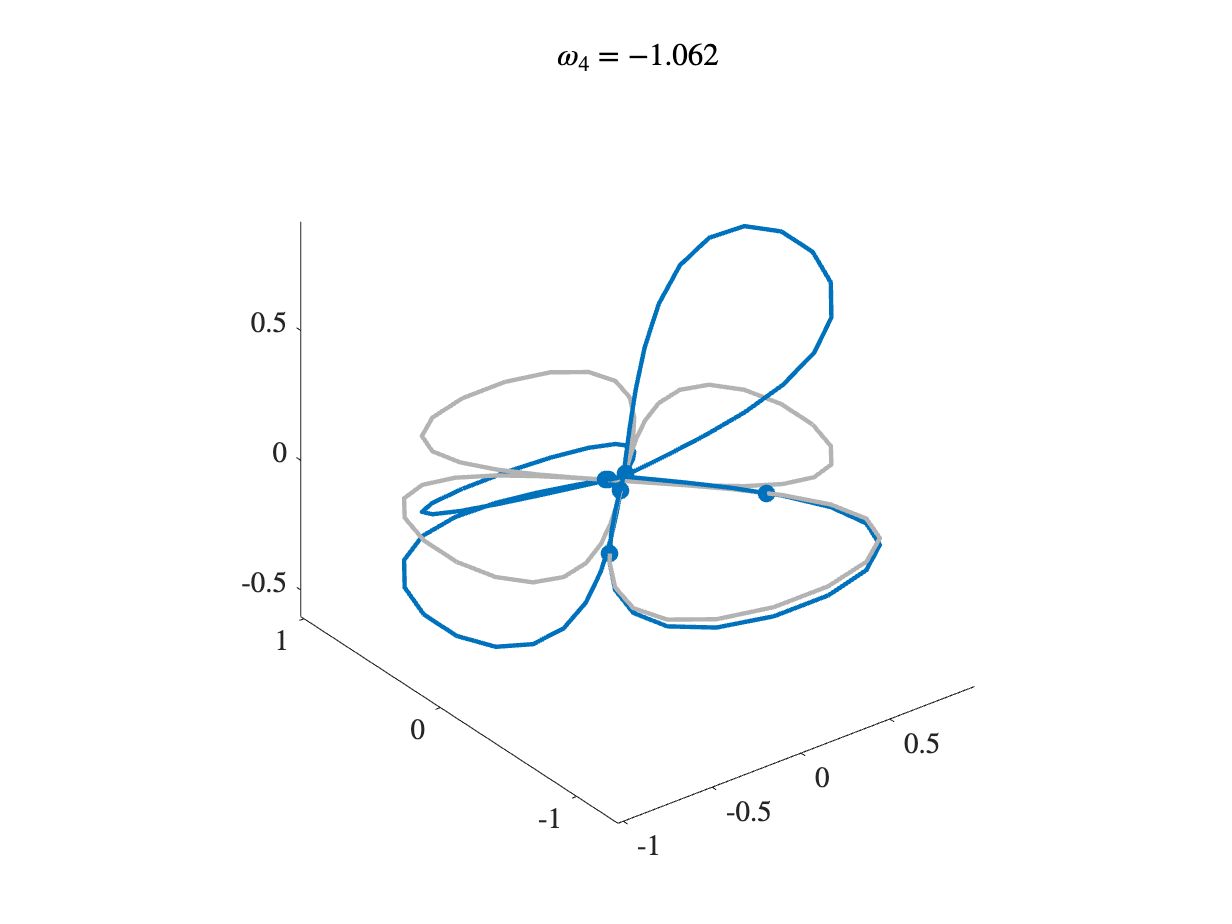

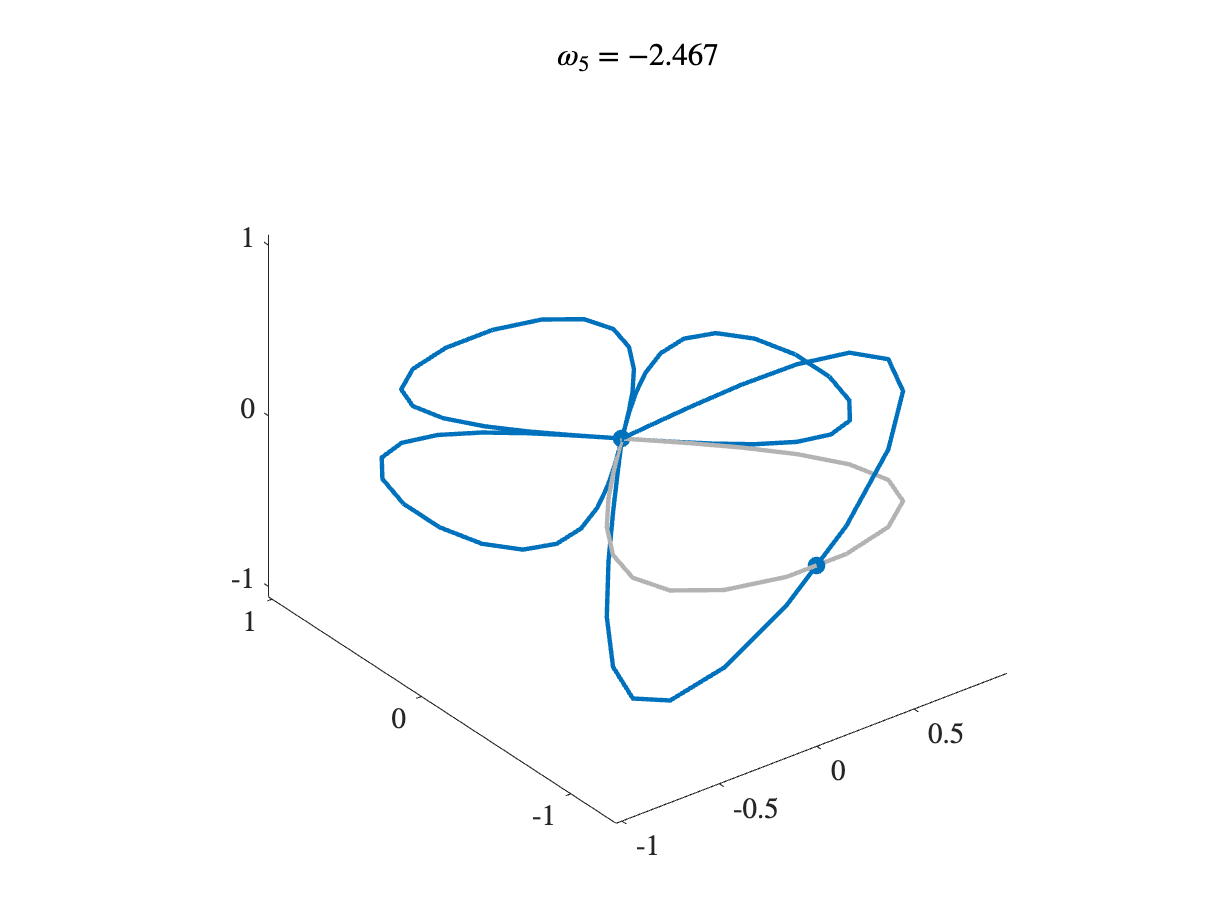

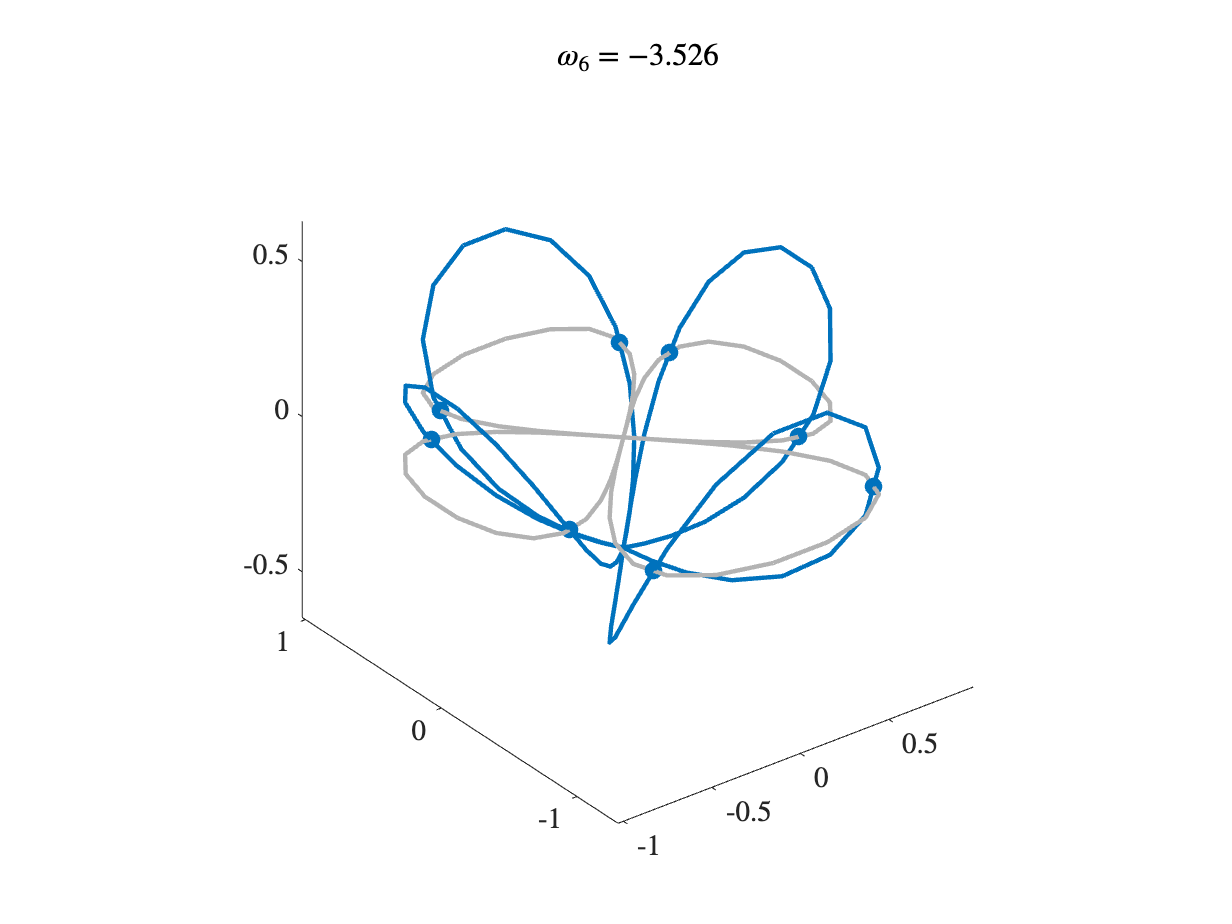

[V2,d2]=Phi2.eigs(numEigs);
for k=1:numEigs
    figure
    Phi2.plot(V2(:,k));
    title(sprintf('$\\omega_{%i} = %0.3f$',k,d2(k)))
end

## A new clover with only the two longest edges of the previous graph

This should have even larger negative eigenvalues

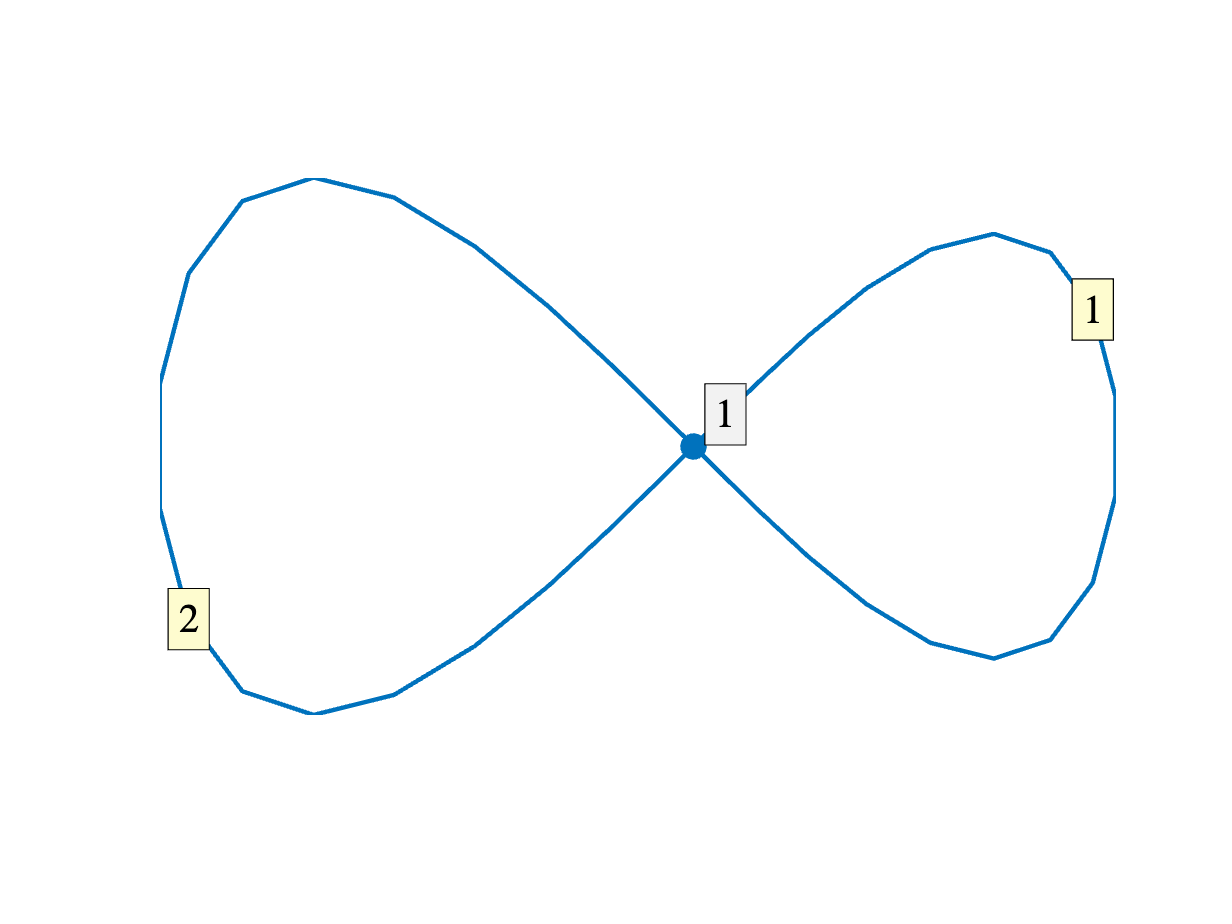

L=sort(L);
L = L(3:4);
Phi3= quantumGraphFromTemplate('clover',nLeaves=2,Lvec=L,discretization='Chebyshev');
Phi3.plot('layout');

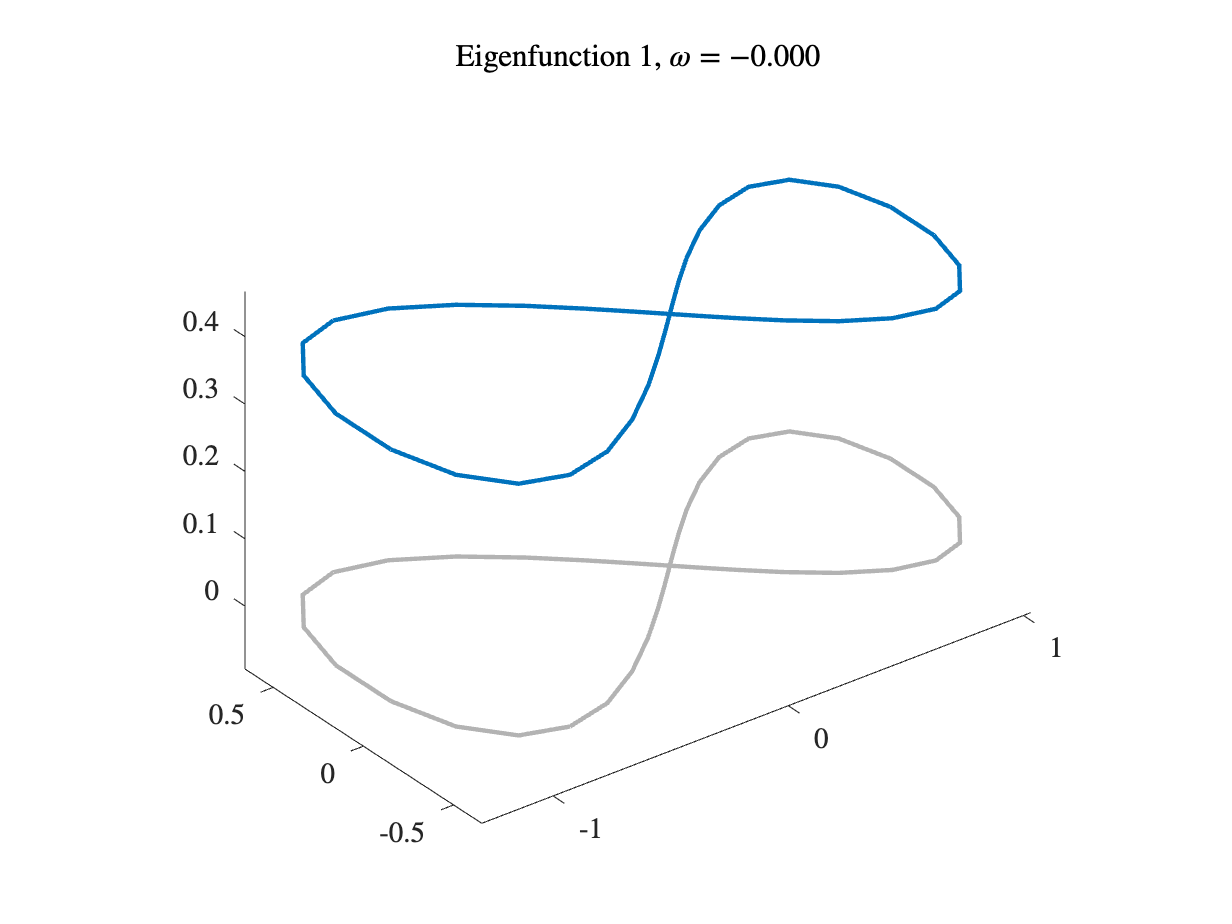

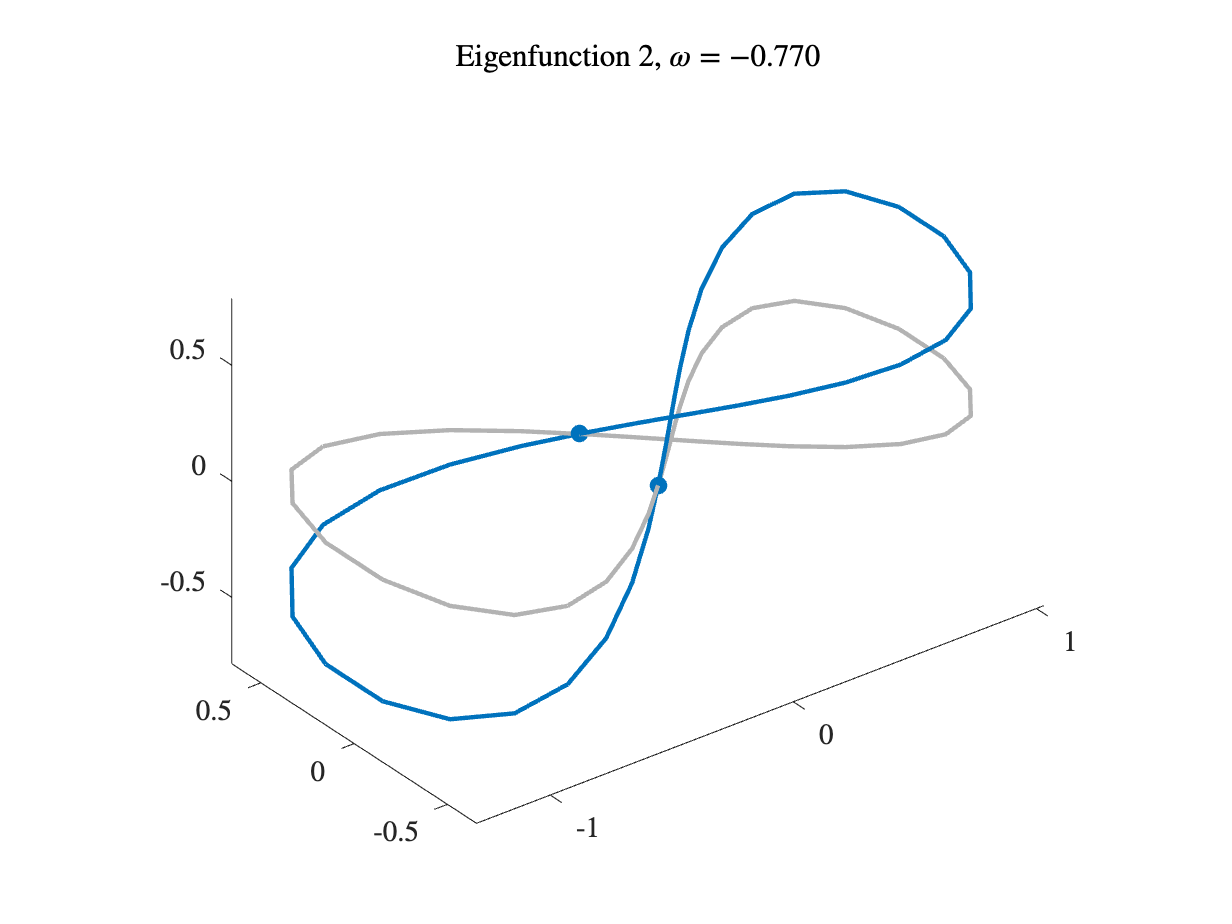

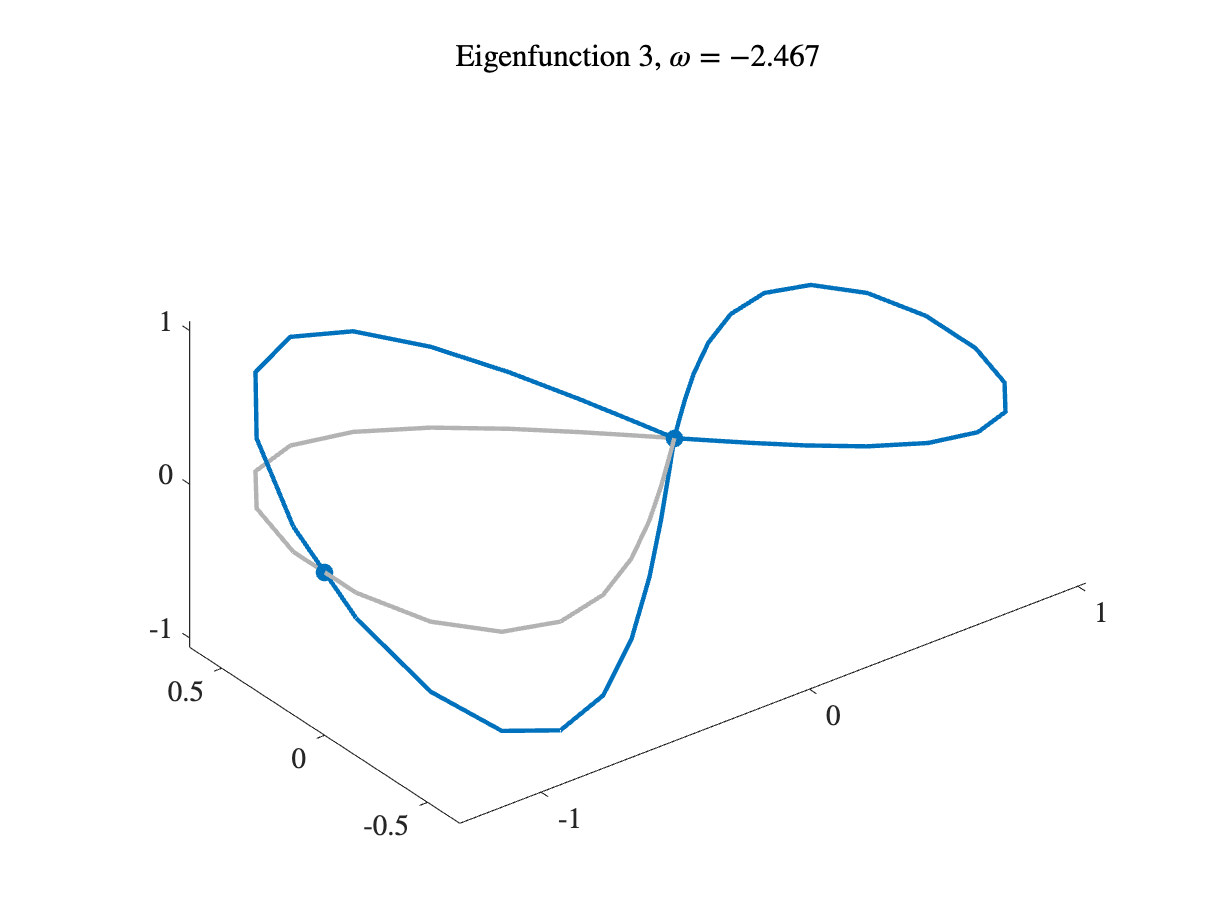

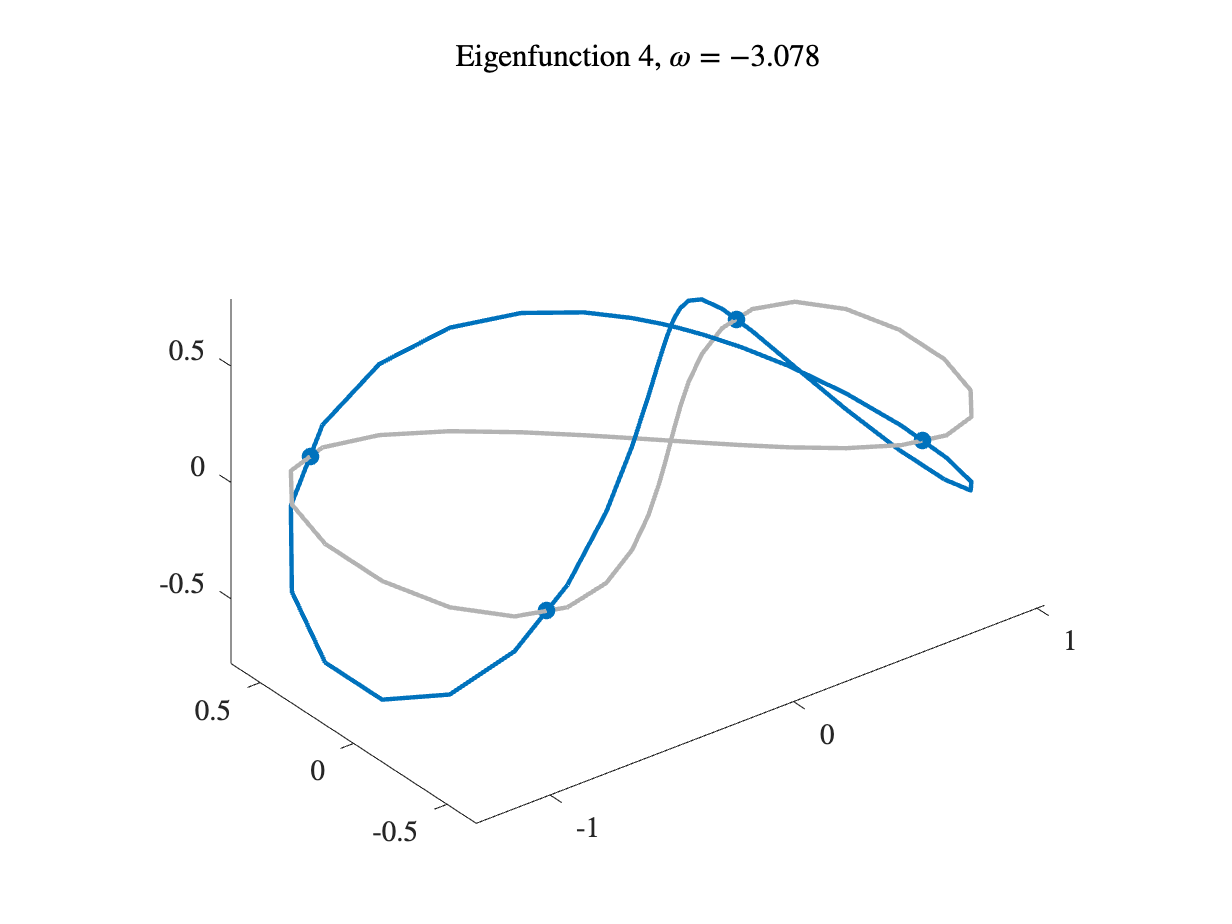

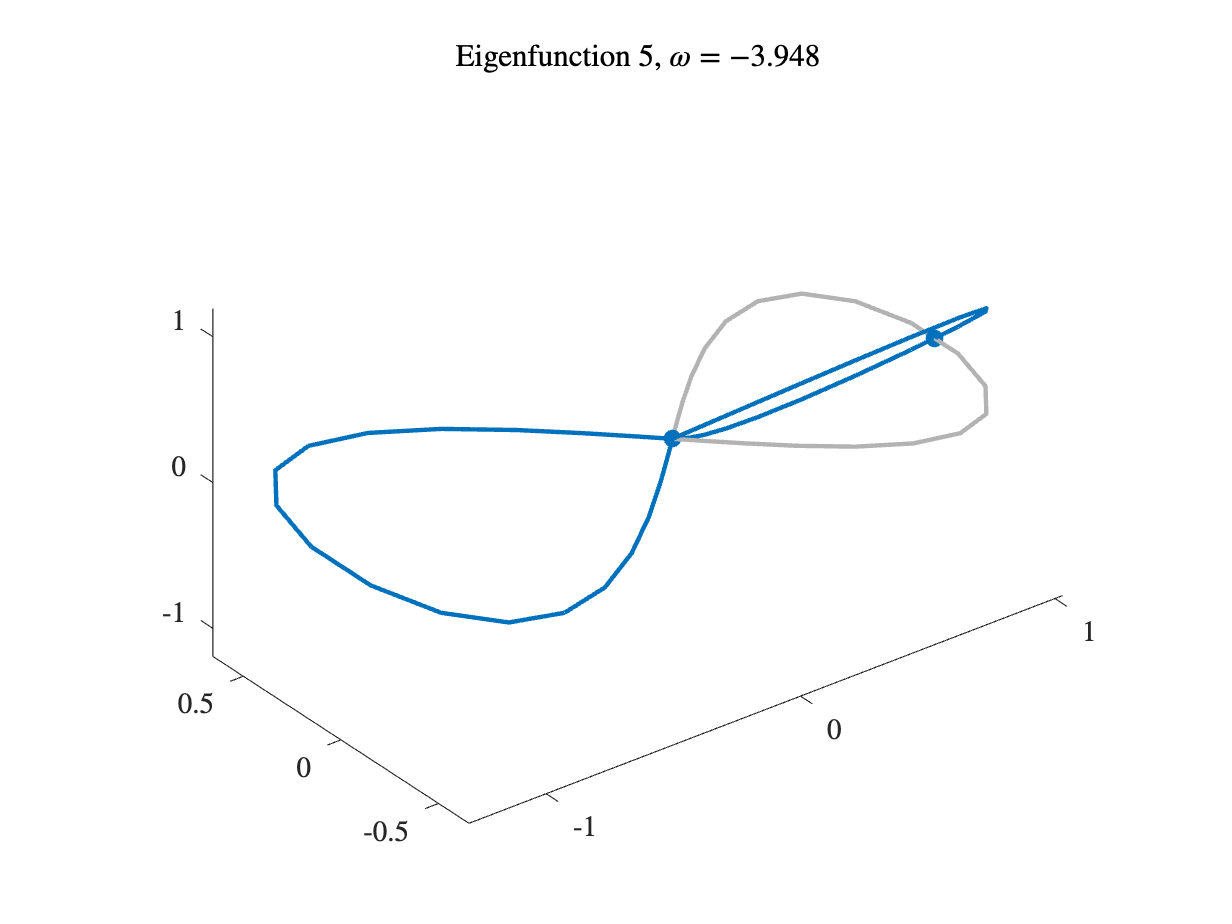

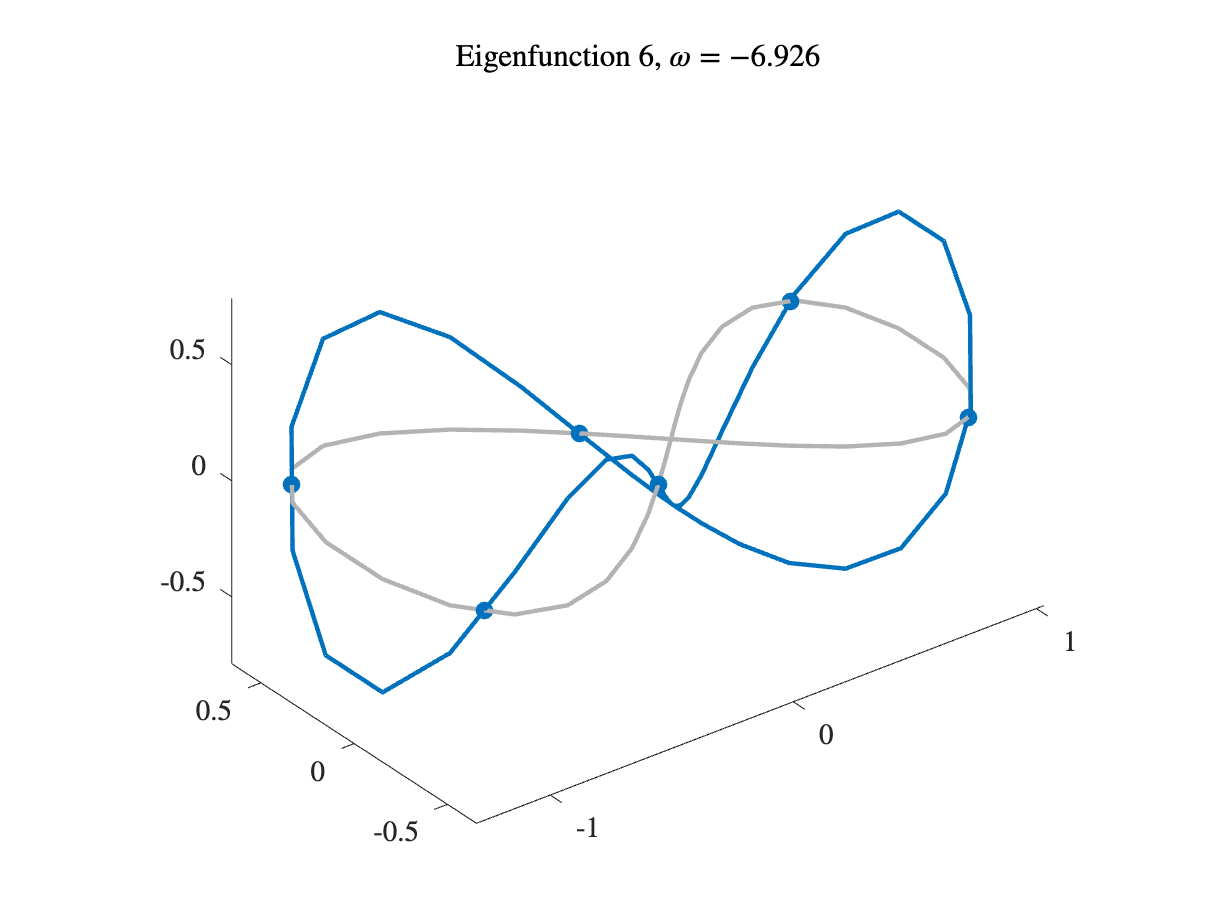

[V3,d3]=Phi3.eigs(numEigs);
for k=1:numEigs
    figure
    Phi3.plot(V3(:,k));
    title(sprintf('Eigenfunction %i, $\\omega = %0.3f$',k,d3(k)))
end

## Comparing the eigenvalues

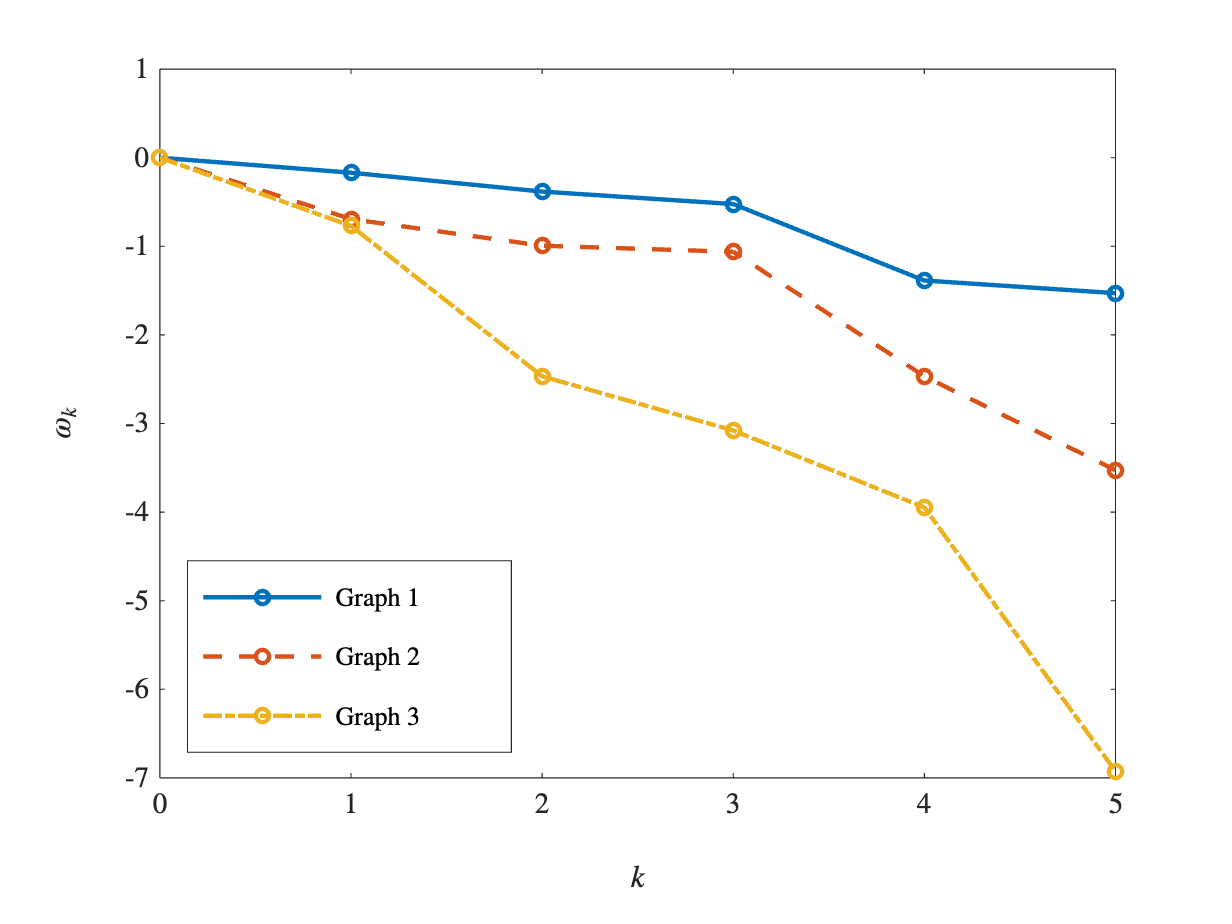

nn = 0:numEigs-1;
plot(nn,d1,'-o',nn,d2,'--o',nn,d3,'-.o')%,nn,w,'x')
xlabel('$k$')
ylabel('$\omega_k$')
legend('Graph 1','Graph 2','Graph 3','Location','southwest')